clc, clear, close all

# Data Preparation

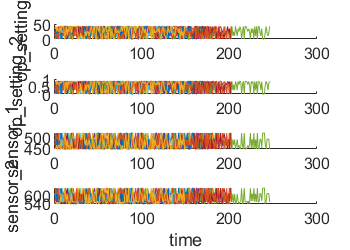

% Load train data
degradationData = helperLoadData('train_FD002.txt');

% Split the degradation data into a training data set 
% and a validation data set for later performance evaluation
rng('default')  % For repeatablility
numEnsemble = length(degradationData);
numFold = 5;
cv = cvpartition(numEnsemble, 'KFold', numFold);
trainData = degradationData(training(cv, 1));
validationData = degradationData(test(cv, 1));

% Specify groups of variables of interest
varNames = string(degradationData{1}.Properties.VariableNames);
timeVariable = varNames{2};
conditionVariables = varNames(3:5);
dataVariables = varNames(6:26);

% Visualize a sample of the ensemble data
nsample = 10;
figure('Units', 'pixels', 'Position', [299, 101, 1100, 789])
helperPlotEnsemble(trainData, timeVariable, [conditionVariables(1:2) dataVariables(1:2)], nsample)

# Working Regime Clustering

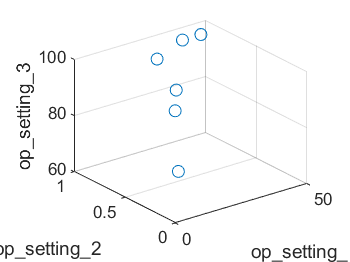

%% Working Regime Clustering
% Notice that each ensemble member contains 3 operating conditions: "op_setting_1", "op_setting_2", and "op_setting_3". 
% Firstly, extract the table from each cell and concatenate them into a single table.
trainDataUnwrap = vertcat(trainData{:});
opConditionUnwrap = trainDataUnwrap(:, cellstr(conditionVariables));

% Visualize all operating points on a 3D scatter plot.
% It clearly shows 6 regimes and the points in each regime are in very close proximity.
figure(2)
helperPlotClusters(opConditionUnwrap)

% Use clustering techniques to locate the 6 clusters automatically. 
% Repeat the K-means clustering algorithm several times with different initial conditions and pick the results with the lowest cost
opts = statset('Display', 'final');
[clusterIndex, centers] = kmeans(table2array(opConditionUnwrap), 6, ... 
    'Distance', 'sqeuclidean', 'Replicates', 5, 'Options', opts);

Replicate 1, 1 iterations, total sum of distances = 0.331378.
Replicate 2, 1 iterations, total sum of distances = 0.331378.
Replicate 3, 1 iterations, total sum of distances = 0.331378.
Replicate 4, 1 iterations, total sum of distances = 0.331378.
Replicate 5, 1 iterations, total sum of distances = 0.331378.
Best total sum of distances = 0.331378


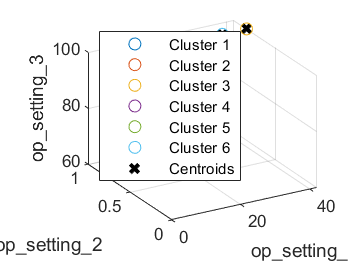

% Visualize the clustering results and the identified cluster centroids
figure(3)
helperPlotClusters(opConditionUnwrap, clusterIndex, centers)

# Working Regime Normalization

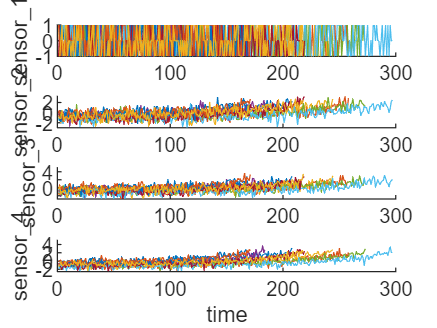

%% Working Regime Normalization
centerstats = struct('Mean', table(), 'SD', table());
for v = dataVariables
    centerstats.Mean.(char(v)) = splitapply(@mean, trainDataUnwrap.(char(v)), clusterIndex);
    centerstats.SD.(char(v))   = splitapply(@std,  trainDataUnwrap.(char(v)), clusterIndex);
end

trainDataNormalized = cellfun(@(data) regimeNormalization(data, centers, centerstats), ...
    trainData, 'UniformOutput', false);

figure(4)
helperPlotEnsemble(trainDataNormalized, timeVariable, dataVariables(1:4), nsample)

# Trendability Analysis

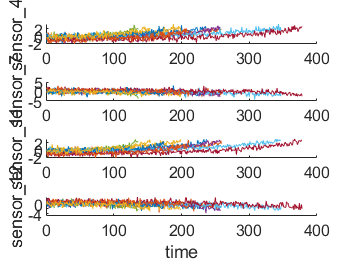

numSensors = length(dataVariables);
signalSlope = zeros(numSensors, 1);
warn = warning('off');
for ct = 1:numSensors
    tmp = cellfun(@(tbl) tbl(:, cellstr(dataVariables(ct))), trainDataNormalized, 'UniformOutput', false);
    mdl = linearDegradationModel(); % create model
    fit(mdl, tmp); % train mode
    signalSlope(ct) = mdl.Theta;
end
warning(warn);

[~, idx] = sort(abs(signalSlope), 'descend');
sensorTrended = sort(idx(1:8));

figure(5)
helperPlotEnsemble(trainDataNormalized, timeVariable, dataVariables(sensorTrended(3:6)), nsample)

# Construct Health Indicator

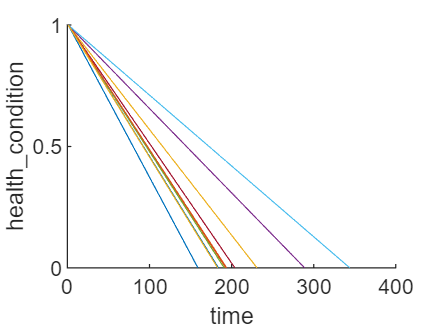

for j=1:numel(trainDataNormalized)
    data = trainDataNormalized{j};
    rul = max(data.time)-data.time;
    data.health_condition = rul / max(rul);
    trainDataNormalized{j} = data;
end

figure(6)
helperPlotEnsemble(trainDataNormalized, timeVariable, "health_condition", nsample)

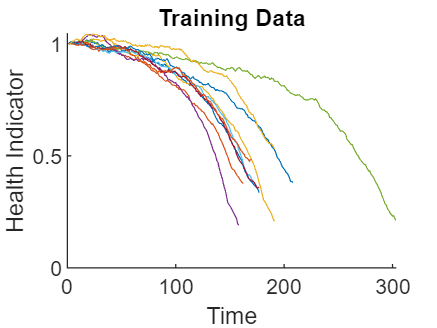

trainDataNormalizedUnwrap = vertcat(trainDataNormalized{:});

sensorToFuse = dataVariables(sensorTrended);
X = trainDataNormalizedUnwrap{:, cellstr(sensorToFuse)};
y = trainDataNormalizedUnwrap.health_condition;
regModel = fitlm(X, y);
bias = regModel.Coefficients.Estimate(1);
weights = regModel.Coefficients.Estimate(2:end);

% Construct a single health indicator by multiplying the sensor measurements with their associated weights
trainDataFused = cellfun(@(data) degradationSensorFusion(data, sensorToFuse, weights), trainDataNormalized, ...
    'UniformOutput', false);% trainDataFused, 208x1 cell

% Visualize the fused health indicator for training data
figure(7)
helperPlotEnsemble(trainDataFused, [], 1, nsample)
xlabel('Time')
ylabel('Health Indicator')
title('Training Data')

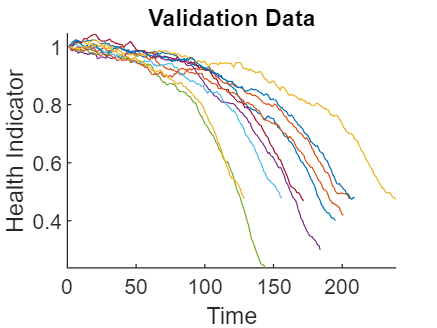

% Verify the trendability of the health indicator of validation data
validationDataNormalized = cellfun(@(data) regimeNormalization(data, centers, centerstats), ...
    validationData, 'UniformOutput', false);
validationDataFused = cellfun(@(data) degradationSensorFusion(data, sensorToFuse, weights), ...
    validationDataNormalized, 'UniformOutput', false);

figure(8)
helperPlotEnsemble(validationDataFused, [], 1, nsample)
xlabel('Time')
ylabel('Health Indicator')
title('Validation Data')

# Build similarity RUL Model

mdl = residualSimilarityModel(...
    'Method', 'poly2',...
    'Distance', 'absolute',...
    'NumNearestNeighbors', 50,...
    'Standardize', 1);

fit(mdl, trainDataFused);
mdl

mdl =   residualSimilarityModel with properties:

                 Models: {208×1 cell}
               ModelMSE: [208×1 double]
               LifeSpan: [208×1 double]
    NumNearestNeighbors: 50
                 Method: "poly2"
               Distance: "absolute"
            IncludeTies: 1
            Standardize: 1
       LifeTimeVariable: ""
           LifeTimeUnit: ""
          DataVariables: ""
               UserData: []
            UseParallel: 0


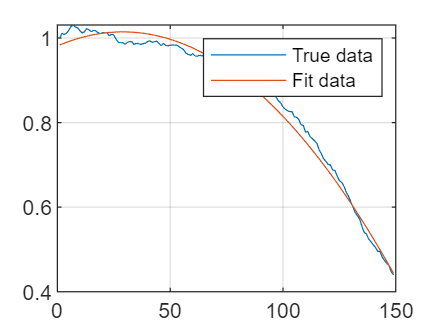

truedata = trainDataFused{1, 1};
coefficients = mdl.Models{1};
time = 1:numel(truedata);
fitdata = coefficients(3)+ coefficients(2)*time + coefficients(1)*time.^2;

figure
hold on
plot(truedata)
plot(fitdata)
legend('True data', 'Fit data');
hold off
grid on
box on

# Performance Evaluation

% To evaluate the similarity RUL model, use 50%, 70% and 90% of a sample validation data to predict its RUL.
breakpoint = [0.5, 0.7, 0.9];
validationDataTmp = validationDataFused{3}; % use one validation data for illustration

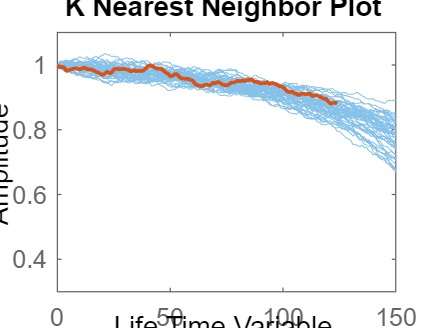

% Use the validation data before the first breakpoint, 50% of the lifetime
bpidx = 1;
validationDataTmp50 = validationDataTmp(1:ceil(end*breakpoint(bpidx)),:);
trueRUL = length(validationDataTmp) - length(validationDataTmp50);
[estRUL, ciRUL, pdfRUL] = predictRUL(mdl, validationDataTmp50);
% Visualize the validation data truncated at 50% 
% and its nearest neighbors.
figure(9)
compare(mdl, validationDataTmp50);

diffRUL50 = trueRUL-estRUL

diffRUL50 = 23.0634

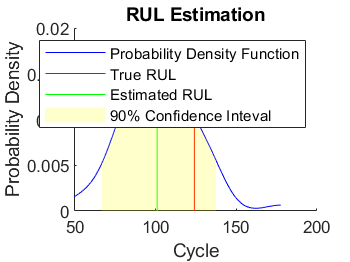

% Visualize the estimated RUL compared to the true RUL and the probability distribution of the estimated RUL.
figure(10)
helperPlotRULDistribution(trueRUL, estRUL, pdfRUL, ciRUL)

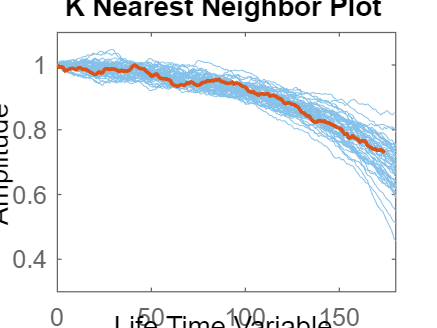

% Use the validation data before the second breakpoint, 70% of the lifetime
bpidx = 2;
validationDataTmp70 = validationDataTmp(1:ceil(end*breakpoint(bpidx)), :);
trueRUL = length(validationDataTmp) - length(validationDataTmp70);
[estRUL, ciRUL, pdfRUL] = predictRUL(mdl, validationDataTmp70);
figure(11)
compare(mdl, validationDataTmp70);

diffRUL70 = trueRUL-estRUL

diffRUL70 = 13.8251

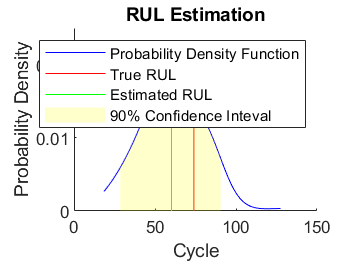

figure(12)
helperPlotRULDistribution(trueRUL, estRUL, pdfRUL, ciRUL)

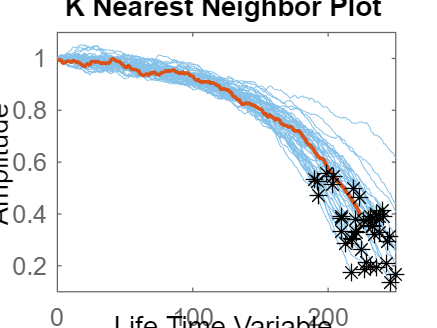

% Use the validation data before the second breakpoint, 90% of the lifetime
bpidx = 3;
validationDataTmp90 = validationDataTmp(1:ceil(end*breakpoint(bpidx)), :);
trueRUL = length(validationDataTmp) - length(validationDataTmp90);
[estRUL, ciRUL, pdfRUL] = predictRUL(mdl, validationDataTmp90);
figure(13)
compare(mdl, validationDataTmp90);

diffRUL90 = trueRUL-estRUL

diffRUL90 = 10.0474

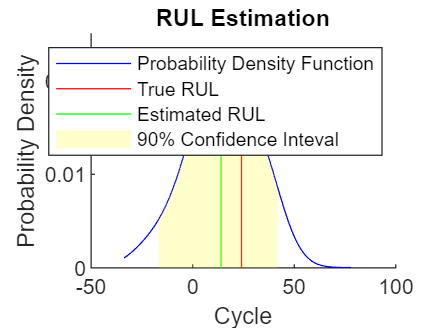

figure
helperPlotRULDistribution(trueRUL, estRUL, pdfRUL, ciRUL)

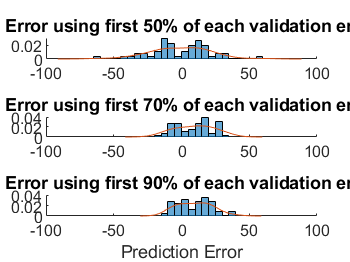

% Repeat the same evaluation procedure fo the whole validation data set
numValidation = length(validationDataFused);
numBreakpoint = length(breakpoint);
error = zeros(numValidation, numBreakpoint);
for dataIdx = 1:numValidation
    tmpData = validationDataFused{dataIdx};
    for bpidx = 1:numBreakpoint
        tmpDataTest = tmpData(1:ceil(end*breakpoint(bpidx)), :);
        trueRUL = length(tmpData) - length(tmpDataTest);
        [estRUL, ~, ~] = predictRUL(mdl, tmpDataTest);
        error(dataIdx, bpidx) = estRUL - trueRUL;
    end
end
[pdf50, x50] = ksdensity(error(:, 1));
[pdf70, x70] = ksdensity(error(:, 2));
[pdf90, x90] = ksdensity(error(:, 3));
figure(14)
ax(1) = subplot(3,1,1);
hold on
histogram(error(:, 1), 'BinWidth', 5, 'Normalization', 'pdf')
plot(x50, pdf50)
hold off
title('RUL Prediction Error using first 50% of each validation ensemble member')
ax(2) = subplot(3,1,2);
hold on
histogram(error(:, 2), 'BinWidth', 5, 'Normalization', 'pdf')
plot(x70, pdf70)
hold off
title('RUL Prediction Error using first 70% of each validation ensemble member')
ax(3) = subplot(3,1,3);
hold on
histogram(error(:, 3), 'BinWidth', 5, 'Normalization', 'pdf')
plot(x90, pdf90)
hold off
xlabel('Prediction Error')
title('RUL Prediction Error using first 90% of each validation ensemble member')
linkaxes(ax, 'x')

Plot the prediction error in a box plot to visualize the median, 25-75 quantile and outliers.

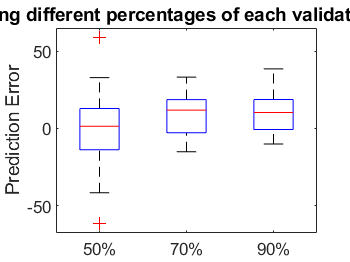

figure
boxplot(error, 'Labels', {'50%', '70%', '90%'})
ylabel('Prediction Error')
title('Prediction error using different percentages of each validation ensemble member')

errorMean = mean(error)

errorMean =    -1.1217    9.5186    9.6540


errorMedian = median(error)

errorMedian =     1.3798   11.8172   10.3457


errorSD = std(error)

errorSD =    21.7315   13.5194   12.3083


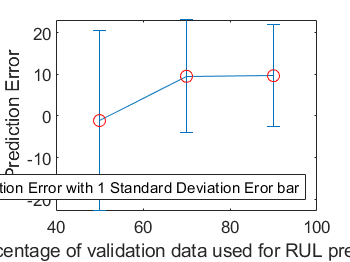

figure
errorbar([50 70 90], errorMean, errorSD, '-o', 'MarkerEdgeColor','r')
xlim([40, 100])
xlabel('Percentage of validation data used for RUL prediction')
ylabel('Prediction Error')
legend('Mean Prediction Error with 1 Standard Deviation Eror bar', 'Location', 'south')

It is shown that the error becomes more concentrated around 0 (less outliers) as more data is observed.

# Custom Functions

## helperLoadData

function degradationData = helperLoadData(filename)
% Copyright 2017-2018 The MathWorks, Inc.

% Load the text file as a table
t = readtable(filename);

% Add variable names to the table
VarNames = {...
    'id', 'time', 'op_setting_1', 'op_setting_2', 'op_setting_3', ...
    'sensor_1', 'sensor_2', 'sensor_3', 'sensor_4', 'sensor_5', ...
    'sensor_6', 'sensor_7', 'sensor_8', 'sensor_9', 'sensor_10', ...
    'sensor_11', 'sensor_12', 'sensor_13', 'sensor_14', 'sensor_15', ...
    'sensor_16', 'sensor_17', 'sensor_18', 'sensor_19', 'sensor_20', ...
    'sensor_21'};
t.Properties.VariableNames = VarNames;

% Split the signals from each machine ID into individual tables 
% and collect the tables in a cell array.
IDs = t{:,1};
nID = unique(IDs);
degradationData = cell(numel(nID),1);
for ct=1:numel(nID)
    idx = IDs == nID(ct);
    degradationData{ct} = t(idx,:);
end
end

## helperPlotEnsemble

function helperPlotEnsemble(ensemble, TimeVariable, DataVariables, nsample, varargin)
% Copyright 2017-2018 The MathWorks, Inc.
% ensemble, 208x1 cell

% Randomly select 10(nsample) machines
randIdx = randperm(length(ensemble));
ensembleSample = ensemble(randIdx(1:nsample));

% Plot profiles
numData = length(DataVariables);
for i = 1:numData
    data2plot = DataVariables(i);
    subplot(numData, 1, i)
    hold on
    for j = 1:length(ensembleSample)
        ensembleMember = ensembleSample{j};
        if isa(ensembleMember, 'double') % Determine if input is 'double' class
            % TimeVariable and DataVariables are doubles
            if isempty(TimeVariable)
                plot(ensembleMember(:, DataVariables), varargin{:})
            else
                plot(ensembleMember(:, TimeVariable), ensembleMember(:, DataVariables), varargin{:})
            end
            xlblstr = "time";
            ylblstr = "Var " + data2plot;
        else
            % ensembleMember is a table
            plot(ensembleMember.(char(TimeVariable)), ensembleMember.(char(data2plot)), varargin{:})
            xlblstr = TimeVariable;
            ylblstr = data2plot;
        end
    end
    hold off
    ylabel(ylblstr, 'Interpreter', 'none')
end
xlabel(xlblstr)
end

## helperPlotClusters

function helperPlotClusters(X, idx, C)
% Copyright 2017-2018 The MathWorks, Inc.

if(nargin>1)
    hold on
    for i = 1:max(idx)
        scatter3(X{idx==i,1}, X{idx==i,2}, X{idx==i,3});
    end
    scatter3(C(:,1),C(:,2),C(:,3), 'x', 'MarkerFaceColor', [0 0 0], ...
        'MarkerEdgeColor', [0 0 0], 'LineWidth', 2);
    legendStr = ["Cluster "+(1:6), "Centroids"];
    legend(cellstr(legendStr), 'Location', 'NW');
    hold off
    view(-30,30)
    grid on
else
    scatter3(X{:,1}, X{:,2}, X{:,3});
end
xlabel(X.Properties.VariableNames{1}, 'Interpreter', 'none')
ylabel(X.Properties.VariableNames{2}, 'Interpreter', 'none')
zlabel(X.Properties.VariableNames{3}, 'Interpreter', 'none')
end

## regimeNormalization

function data = regimeNormalization(data, centers, centerstats)
% Perform normalization for each observation (row) of the data
% according to the cluster the observation belongs to.
conditionIdx = 3:5;
dataIdx = 6:26;

% Perform row-wise operation
data{:, dataIdx} = table2array(...
    rowfun(@(row) localNormalize(row, conditionIdx, dataIdx, centers, centerstats), ...
    data, 'SeparateInputs', false));
end

## **localNormalize**

function rowNormalized = localNormalize(row, conditionIdx, dataIdx, centers, centerstats)
% Normalization operation for each row.

% Get the operating points and sensor measurements
ops = row(1, conditionIdx);
sensor = row(1, dataIdx);

% Find which cluster center is the closest
dist = sum((centers - ops).^2, 2);
[~, idx] = min(dist);

% Normalize the sensor measurements by the mean and standard deviation of the cluster.
% Reassign NaN and Inf to 0.
rowNormalized = (sensor - centerstats.Mean{idx, :}) ./ centerstats.SD{idx, :};
rowNormalized(isnan(rowNormalized) | isinf(rowNormalized)) = 0;
end

## degradationSensorFusion

function dataFused = degradationSensorFusion(data, sensorToFuse, weights)
% Combine measurements from different sensors according 
% to the weights, smooth the fused data and offset the data
% so that all the data start from 1

% Fuse the data according to weights
dataToFuse = data{:, cellstr(sensorToFuse)};
dataFusedRaw = dataToFuse*weights;

% Smooth the fused data with moving mean
stepBackward = 10;
stepForward = 10;
dataFused = movmean(dataFusedRaw, [stepBackward stepForward]);

% Offset the data to 1
dataFused = dataFused + 1 - dataFused(1);
end

## helperPlotRULDsitribution

function helperPlotRULDistribution(trueRUL, estRUL, pdfRUL, ciRUL)
% HELPERPLOTRULDISTRIBUTION Plot RUL distribution
%
% This function supports the Similarity-based Remaining Useful Life
% Estimation example. It may change in a future release.

%  Copyright 2017-2018 The MathWorks, Inc.

hold on
plot(pdfRUL.RUL, pdfRUL.ProbabilityDensity, 'b');
idx = find(pdfRUL.RUL > trueRUL, 1, 'first');
if isempty(idx)
    y = pdfRUL.ProbabilityDensity(end);
else
    y = pdfRUL.ProbabilityDensity(idx);
end
plot([trueRUL, trueRUL], [0, y], 'r');
idx = find(pdfRUL.RUL > estRUL, 1, 'first');
if isempty(idx)
    y = pdfRUL.ProbabilityDensity(end);
else
    y = pdfRUL.ProbabilityDensity(idx);
end
plot([estRUL, estRUL], [0, y], 'g');
idx = pdfRUL.RUL >= ciRUL(1) & pdfRUL.RUL<=ciRUL(2);
area(pdfRUL.RUL(idx), pdfRUL.ProbabilityDensity(idx), ...
    'FaceAlpha', 0.2, 'FaceColor', 'y', 'EdgeColor', 'none');
hold off
legend('Probability Density Function', 'True RUL', 'Estimated RUL', '90% Confidence Inteval');
xlabel('Cycle')
ylabel('Probability Density')
title('RUL Estimation')
end

# Reference

[1]  A. Saxena and K. Goebel (2008). "PHM08 Challenge Data Set", NASA Ames Prognostics Data Repository (http://ti.arc.nasa.gov/project/prognostic-data-repository), NASA Ames Research Center, Moffett Field, CA

[2] Roemer, Michael J., Gregory J. Kacprzynski, and Michael H. Schoeller. "Improved diagnostic and prognostic assessments using health management information fusion." AUTOTESTCON Proceedings, 2001. IEEE Systems Readiness Technology Conference. IEEE, 2001.

[3] Goebel, Kai, and Piero Bonissone. "Prognostic information fusion for constant load systems." Information Fusion, 2005 8th International Conference on. Vol. 2. IEEE, 2005.

[4] Wang, Peng, and David W. Coit. "Reliability prediction based on degradation modeling for systems with multiple degradation measures." Reliability and Maintainability, 2004 Annual Symposium-RAMS. IEEE, 2004.

[5] Jardine, Andrew KS, Daming Lin, and Dragan Banjevic. "A review on machinery diagnostics and prognostics implementing condition-based maintenance." Mechanical systems and signal processing 20.7 (2006): 1483-1510.